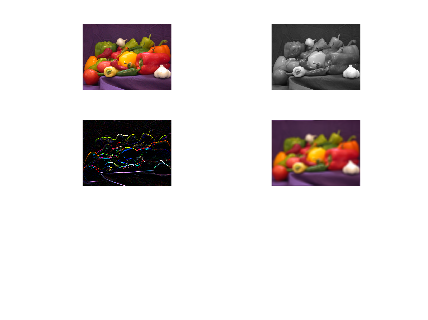

% Exercise 1a
figure
I = imread('peppers.png');
subplot(321);
imshow(I);
Is = rgb2gray(I);
subplot(322); imshow(Is);
h = fspecial('sobel');
If = imfilter(I, h,'conv','circular');
subplot(323)
imshow(If);
h1=ones(15,15);
h = h1/sum(sum(h1));
If = imfilter(I, h,'conv','circular');
subplot(324);
imshow(If);

## 1b

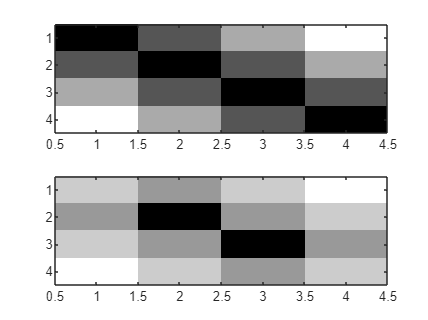

figure
A=[0 16 32 48;16 0 16 32;32 16 0 16;48 32 16 0];
h=1/9.*ones(3,3);
lf=imfilter(A,h,'conv','circular');
ax1=subplot(211);imagesc(A);colormap(ax1,'gray');
ax2=subplot(212);imagesc(lf);colormap(ax2,'gray');